# Asesoria Métodos Númericos

### Asesoria 03/05/2022

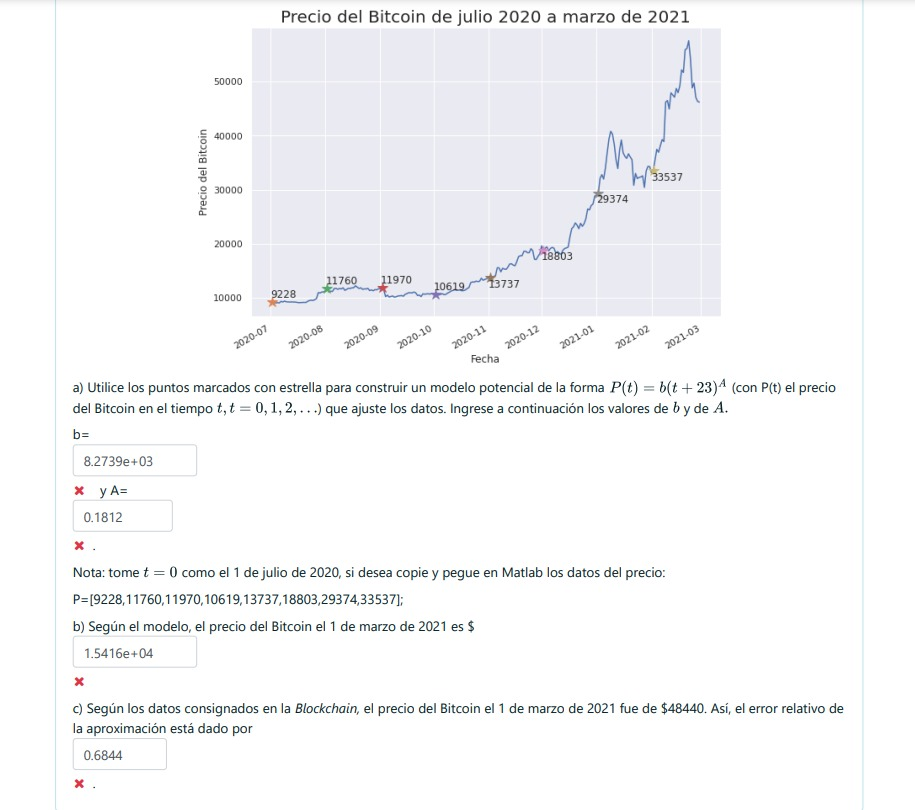

clear

t = 0:5;
B = [9228 11760 11970 10619 13737 1880];

[A, B] = lsline(log(t + 23), log(B));
% Valores:
A, exp(B)

A = -5.3340

ans = 2.6458e+11

P = @(t) exp(B) .* (t + 23).^A;
P(8)

ans = 2.9352e+03

RErr = abs( P(8) - 48440 ) / 48440

RErr = 0.9394

clear

X = [0 0.2857 .5714 .8571 1.1429 1.4286 1.7143];
Y = [1 2.0929 2.9604 3.8445 4.8534 6.0770 7.6141];

help lsline

  Entrada  - X es el vector de abscisas   1 x n
           - Y es el vector de ordenadas  1 x n
  Salida   - A es el coeficiente de  x  en  Ax + B
           - B es el coeficiente constante en  Ax + B



[A1, b1] = lsline(X, Y)

A1 = 3.7128

b1 = 0.8807

X = [0 0.2857 .5714 .8571 1.1429 1.4286 1.7143 .4];
Y = [1 2.0929 2.9604 3.8445 4.8534 6.0770 7.6141 5];

[A2, b2] = lsline(X, Y)

A2 = 3.2860

b2 = 1.5515

Dif = 180 / pi * atan( (A2 - A1) / (1 + A1*A2) )

Dif = -1.8519

### Asesoria 06/05/2022

% No se reciben preguntas el dia de la asesoria